# Task Status Table

Create a figure with a grid layout

figObj = uifigure("Position",[100 100 250 225]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

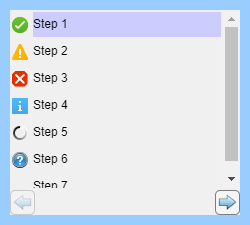

taskStatusWidget = wt.TaskStatusTable(gridObj);

taskStatusWidget.ButtonPushedFcn = @(src,evt)disp(evt)

taskStatusWidget =   TaskStatusTable with properties:

    ButtonPushedFcn: @(src,evt)disp(evt)

              Items: [7×1 string]
             Status: [7×1 wt.enum.StatusState]
          RowHeight: 25
      SelectedIndex: 1
     SelectionColor: [0.8000 0.8000 1]
      ShowButtonRow: on
      StatusMessage: ""
      EnableForward: on
         EnableBack: on
            Tooltip: ""
        ButtonColor: [0.9600 0.9600 0.9600]

           Position: [11 11 230 205]
              Units: 'pixels'

  Show all properties


Set the items in the widget:

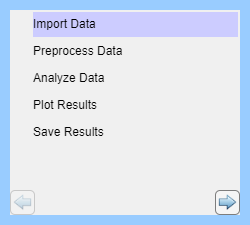

taskStatusWidget.Items = [
    "Import Data"
    "Preprocess Data"
    "Analyze Data"
    "Plot Results"
    "Save Results"
    ];

taskStatusWidget.Status = [
    "none"
    "none"
    "none"
    "none"
    "none"
    ];

Configure the status of each task and select the third one:

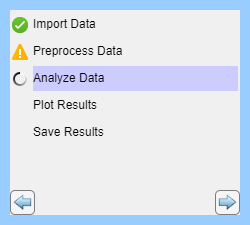

taskStatusWidget.Status = [
    "complete"
    "warning"
    "running"
    "none"
    "none"
    ];

taskStatusWidget.SelectedIndex = 3;

Optionally, display a status message at the bottom:

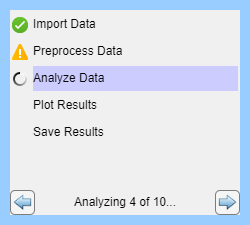

taskStatusWidget.StatusMessage = "Analyzing 4 of 10...";

*Copyright 2020-2025 The MathWorks, Inc.*